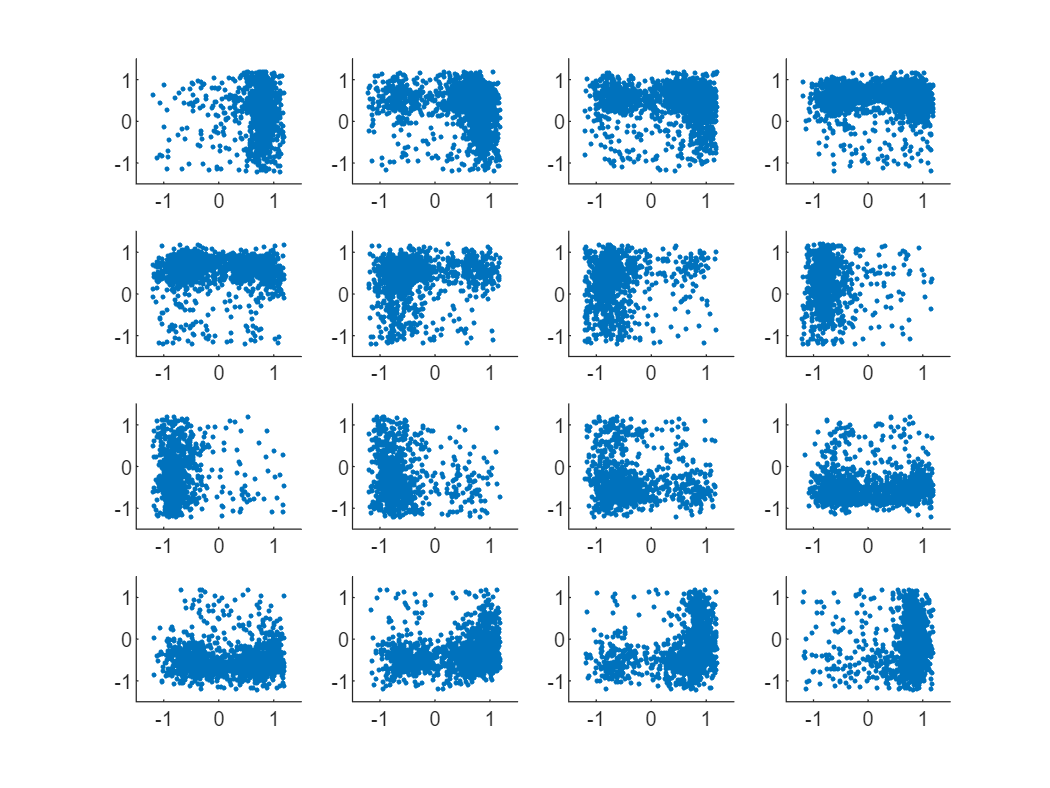

data = load("accumulated_radar_point.txt");
data = data(:,2:end);
idx = find(data(3,:)>pi);
data(3,idx) = data(3,idx) - 2*pi;
idx = find(data(3,:)<-pi);
data(3,idx) = data(3,idx) + 2*pi;
j = 1;
for i = -pi:pi/8:7*pi/8
     idx = find(data(3,:)>i&data(3,:)<i+pi/8);
     subplot(4,4,j);
     j = j+1;
     scatter(data(1,idx),data(2,idx),'.');
     axis([-1.5,1.5,-1.5,1.5]);
end

% idx = find(data(3,:)<1*pi/8 & data(3,:)>-pi/8);
% scatter(data(1,idx),data(2,idx),'.');